# **Curva de torque de um Motor de Indução Trifásico**

Da equação:


$$T_d =3I_{\;2}^2 \frac{R_2 }{s\omega_s }$$


Observamos que um incremento na resistência do rotor ($R_2$) é acompanhado por um decremento na corrente do rotor ($I_2$) para uma mesma força eletromotriz induzida no circuito do rotor. O decremento na corrente do rotor causa a redução no torque desenvolvido ($T_d$). Assim, o incremento ou decremento do torque desenvolvido dependerá de qual parâmetro terá o papel dominante.

Vamos plotar um **gráfico relacionando o torque desenvolvido pela máquina com o escorregamento**. A variação de $s$ vai de 1 até 0, ou seja:

% não podemos colocar zero como um dos limites já que divisão por zero dá um resultado infinito
% 1e-10 é muito próximo de zero
s = ____:-0.001:____

s =     1.0000    0.9990    0.9980    0.9970    0.9960    0.9950    0.9940    0.9930    0.9920    0.9910    0.9900    0.9890    0.9880    0.9870    0.9860    0.9850    0.9840    0.9830    0.9820    0.9810    0.9800    0.9790    0.9780    0.9770    0.9760    0.9750    0.9740    0.9730    0.9720    0.9710    0.9700    0.9690    0.9680    0.9670    0.9660    0.9650    0.9640    0.9630    0.9620    0.9610    0.9600    0.9590    0.9580    0.9570    0.9560    0.9550    0.9540    0.9530    0.9520    0.9510


Para exemplificação, tomemos um Motor de Indução Trifásico (MIT) de 6 polos, 120 V, 50 Hz, conectado em delta. Esse MIT tem os seguintes parâmetros por fase:

- 
$$R_1 =0,5\;\Omega \;$$


- 
$$R_2 =0,25\;\Omega \;$$


- 
$$X_1 =0,75\;\Omega \;$$


- 
$$X_2 =0,5\;\Omega \;$$


- 
$$X_m =100\;\Omega \;$$


- 
$$R_c =500\;\Omega \;$$


Em código:

P = 6;
V1 = 120;
f = 50;

R1 = 0.5;
R2 = 0.25;
X1 = 0.75;
X2 = 0.5;
Xm = 100;
Rc = 500;

A velocidade síncrona para esse motor é:

Ns = 120*f/P;
fprintf('Velocidade síncrona = %.0f rpm', Ns)

Velocidade síncrona = 1000 rpm

Em $\frac{\mathrm{rad}}{s}$:

omega_s = 4*pi*f/P;
fprintf('Velocidade síncrona = %.2f rad/s', omega_s)

Velocidade síncrona = 104.72 rad/s

Calculando as impedâncias, temos:

Z2 = R2./s + X2*1i

Z2 = 	1.0e+02 *

   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0025 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i   0.0026 + 0.0050i


Z1 = R1 + X1*1i

Z1 = 0.5000 + 0.7500i

A impedância equivalente ($Z_e$) é o paralelo de $Z_2$, $R_c$ e ${\mathrm{jX}}_m$, ou seja:


$$\frac{1}{Z_e }=\frac{1}{R_c }+\frac{1}{{\mathrm{jX}}_m }+\frac{1}{Z_2 }$$


Ze = _______________________________

Ze =    0.2479 + 0.4976i   0.2481 + 0.4976i   0.2484 + 0.4976i   0.2486 + 0.4976i   0.2489 + 0.4976i   0.2491 + 0.4976i   0.2494 + 0.4976i   0.2496 + 0.4976i   0.2499 + 0.4976i   0.2501 + 0.4976i   0.2504 + 0.4976i   0.2506 + 0.4976i   0.2509 + 0.4976i   0.2511 + 0.4976i   0.2514 + 0.4976i   0.2517 + 0.4976i   0.2519 + 0.4976i   0.2522 + 0.4976i   0.2524 + 0.4976i   0.2527 + 0.4976i   0.2529 + 0.4977i   0.2532 + 0.4977i   0.2535 + 0.4977i   0.2537 + 0.4977i   0.2540 + 0.4977i   0.2542 + 0.4977i   0.2545 + 0.4977i   0.2548 + 0.4977i   0.2550 + 0.4977i   0.2553 + 0.4977i   0.2555 + 0.4977i   0.2558 + 0.4977i   0.2561 + 0.4977i   0.2563 + 0.4977i   0.2566 + 0.4977i   0.2569 + 0.4977i   0.2571 + 0.4977i   0.2574 + 0.4977i   0.2577 + 0.4977i   0.2579 + 0.4977i   0.2582 + 0.4977i   0.2585 + 0.4977i   0.2587 + 0.4977i   0.2590 + 0.4977i   0.2593 + 0.4977i   0.2595 + 0.4977i   0.2598 + 0.4977i   0.2601 + 0.4977i   0.2604 + 0.4977i   0.2606 + 0.4977i


Assim, a impedância de entrada ($Z_{\mathrm{in}}$) será:


$$Z_{\mathrm{in}} =Z_e +Z_1$$


Zin = ________

Zin =    0.7479 + 1.2476i   0.7481 + 1.2476i   0.7484 + 1.2476i   0.7486 + 1.2476i   0.7489 + 1.2476i   0.7491 + 1.2476i   0.7494 + 1.2476i   0.7496 + 1.2476i   0.7499 + 1.2476i   0.7501 + 1.2476i   0.7504 + 1.2476i   0.7506 + 1.2476i   0.7509 + 1.2476i   0.7511 + 1.2476i   0.7514 + 1.2476i   0.7517 + 1.2476i   0.7519 + 1.2476i   0.7522 + 1.2476i   0.7524 + 1.2476i   0.7527 + 1.2476i   0.7529 + 1.2477i   0.7532 + 1.2477i   0.7535 + 1.2477i   0.7537 + 1.2477i   0.7540 + 1.2477i   0.7542 + 1.2477i   0.7545 + 1.2477i   0.7548 + 1.2477i   0.7550 + 1.2477i   0.7553 + 1.2477i   0.7555 + 1.2477i   0.7558 + 1.2477i   0.7561 + 1.2477i   0.7563 + 1.2477i   0.7566 + 1.2477i   0.7569 + 1.2477i   0.7571 + 1.2477i   0.7574 + 1.2477i   0.7577 + 1.2477i   0.7579 + 1.2477i   0.7582 + 1.2477i   0.7585 + 1.2477i   0.7587 + 1.2477i   0.7590 + 1.2477i   0.7593 + 1.2477i   0.7595 + 1.2477i   0.7598 + 1.2477i   0.7601 + 1.2477i   0.7604 + 1.2477i   0.7606 + 1.2477i


A corrente de entrada, ou corrente do estator, ($I_1$) é da forma:


$$I_1 =\frac{V_1 }{Z_{\mathrm{in}} }$$


I1 = ________

I1 =   42.4148 -70.7566i  42.4214 -70.7442i  42.4279 -70.7318i  42.4345 -70.7193i  42.4411 -70.7069i  42.4478 -70.6944i  42.4544 -70.6818i  42.4610 -70.6693i  42.4676 -70.6567i  42.4743 -70.6441i  42.4809 -70.6315i  42.4876 -70.6188i  42.4943 -70.6062i  42.5009 -70.5935i  42.5076 -70.5807i  42.5143 -70.5680i  42.5210 -70.5552i  42.5277 -70.5424i  42.5344 -70.5296i  42.5412 -70.5167i  42.5479 -70.5038i  42.5547 -70.4909i  42.5614 -70.4780i  42.5682 -70.4650i  42.5749 -70.4521i  42.5817 -70.4390i  42.5885 -70.4260i  42.5953 -70.4129i  42.6021 -70.3999i  42.6089 -70.3867i  42.6158 -70.3736i  42.6226 -70.3604i  42.6294 -70.3472i  42.6363 -70.3340i  42.6431 -70.3208i  42.6500 -70.3075i  42.6569 -70.2942i  42.6638 -70.2808i  42.6706 -70.2675i  42.6776 -70.2541i  42.6845 -70.2407i  42.6914 -70.2272i  42.6983 -70.2138i  42.7052 -70.2003i  42.7122 -70.1867i  42.7191 -70.1732i  42.7261 -70.1596i  42.7331 -70.1460i  42.7401 -70.1324i  42.7470 -70.1187i


Já a força eletromotriz ($E_1$) será:


$$E_1 =V_1 -I_1 Z_1$$


E1 = _________

E1 = 	1.0e+02 *

   0.4573 + 0.0357i   0.4573 + 0.0356i   0.4574 + 0.0354i   0.4574 + 0.0353i   0.4575 + 0.0352i   0.4576 + 0.0351i   0.4576 + 0.0350i   0.4577 + 0.0349i   0.4577 + 0.0348i   0.4578 + 0.0347i   0.4579 + 0.0346i   0.4579 + 0.0344i   0.4580 + 0.0343i   0.4580 + 0.0342i   0.4581 + 0.0341i   0.4582 + 0.0340i   0.4582 + 0.0339i   0.4583 + 0.0338i   0.4584 + 0.0336i   0.4584 + 0.0335i   0.4585 + 0.0334i   0.4585 + 0.0333i   0.4586 + 0.0332i   0.4587 + 0.0331i   0.4587 + 0.0329i   0.4588 + 0.0328i   0.4589 + 0.0327i   0.4589 + 0.0326i   0.4590 + 0.0325i   0.4591 + 0.0324i   0.4591 + 0.0322i   0.4592 + 0.0321i   0.4592 + 0.0320i   0.4593 + 0.0319i   0.4594 + 0.0318i   0.4594 + 0.0317i   0.4595 + 0.0315i   0.4596 + 0.0314i   0.4596 + 0.0313i   0.4597 + 0.0312i   0.4598 + 0.0311i   0.4598 + 0.0310i   0.4599 + 0.0308i   0.4600 + 0.0307i   0.4600 + 0.0306i   0.4601 + 0.0305i   0.4602 + 0.0304i   0.4602 + 0.0302i   0.4603 + 0.0301i   0.4604 + 0.0300i


Em seguida:

$I_c =\frac{E_1 }{R_c }$ e $I_m =\frac{E_1 }{{\mathrm{jX}}_m }$


$$I_{\phi } =I_c +I_m$$


Ic = _________

Ic =    0.0915 + 0.0071i   0.0915 + 0.0071i   0.0915 + 0.0071i   0.0915 + 0.0071i   0.0915 + 0.0070i   0.0915 + 0.0070i   0.0915 + 0.0070i   0.0915 + 0.0070i   0.0915 + 0.0070i   0.0916 + 0.0069i   0.0916 + 0.0069i   0.0916 + 0.0069i   0.0916 + 0.0069i   0.0916 + 0.0068i   0.0916 + 0.0068i   0.0916 + 0.0068i   0.0916 + 0.0068i   0.0917 + 0.0068i   0.0917 + 0.0067i   0.0917 + 0.0067i   0.0917 + 0.0067i   0.0917 + 0.0067i   0.0917 + 0.0066i   0.0917 + 0.0066i   0.0917 + 0.0066i   0.0918 + 0.0066i   0.0918 + 0.0065i   0.0918 + 0.0065i   0.0918 + 0.0065i   0.0918 + 0.0065i   0.0918 + 0.0064i   0.0918 + 0.0064i   0.0918 + 0.0064i   0.0919 + 0.0064i   0.0919 + 0.0064i   0.0919 + 0.0063i   0.0919 + 0.0063i   0.0919 + 0.0063i   0.0919 + 0.0063i   0.0919 + 0.0062i   0.0920 + 0.0062i   0.0920 + 0.0062i   0.0920 + 0.0062i   0.0920 + 0.0061i   0.0920 + 0.0061i   0.0920 + 0.0061i   0.0920 + 0.0061i   0.0920 + 0.0060i   0.0921 + 0.0060i   0.0921 + 0.0060i


Im = _________

Im =    0.0357 - 0.4573i   0.0356 - 0.4573i   0.0354 - 0.4574i   0.0353 - 0.4574i   0.0352 - 0.4575i   0.0351 - 0.4576i   0.0350 - 0.4576i   0.0349 - 0.4577i   0.0348 - 0.4577i   0.0347 - 0.4578i   0.0346 - 0.4579i   0.0344 - 0.4579i   0.0343 - 0.4580i   0.0342 - 0.4580i   0.0341 - 0.4581i   0.0340 - 0.4582i   0.0339 - 0.4582i   0.0338 - 0.4583i   0.0336 - 0.4584i   0.0335 - 0.4584i   0.0334 - 0.4585i   0.0333 - 0.4585i   0.0332 - 0.4586i   0.0331 - 0.4587i   0.0329 - 0.4587i   0.0328 - 0.4588i   0.0327 - 0.4589i   0.0326 - 0.4589i   0.0325 - 0.4590i   0.0324 - 0.4591i   0.0322 - 0.4591i   0.0321 - 0.4592i   0.0320 - 0.4592i   0.0319 - 0.4593i   0.0318 - 0.4594i   0.0317 - 0.4594i   0.0315 - 0.4595i   0.0314 - 0.4596i   0.0313 - 0.4596i   0.0312 - 0.4597i   0.0311 - 0.4598i   0.0310 - 0.4598i   0.0308 - 0.4599i   0.0307 - 0.4600i   0.0306 - 0.4600i   0.0305 - 0.4601i   0.0304 - 0.4602i   0.0302 - 0.4602i   0.0301 - 0.4603i   0.0300 - 0.4604i


Iphi = _________

Iphi =    0.1271 - 0.4501i   0.1270 - 0.4502i   0.1269 - 0.4503i   0.1268 - 0.4504i   0.1267 - 0.4504i   0.1266 - 0.4505i   0.1265 - 0.4506i   0.1264 - 0.4507i   0.1263 - 0.4508i   0.1262 - 0.4509i   0.1261 - 0.4509i   0.1260 - 0.4510i   0.1259 - 0.4511i   0.1258 - 0.4512i   0.1257 - 0.4513i   0.1256 - 0.4514i   0.1255 - 0.4515i   0.1254 - 0.4515i   0.1253 - 0.4516i   0.1252 - 0.4517i   0.1251 - 0.4518i   0.1250 - 0.4519i   0.1249 - 0.4520i   0.1248 - 0.4521i   0.1247 - 0.4521i   0.1246 - 0.4522i   0.1245 - 0.4523i   0.1244 - 0.4524i   0.1243 - 0.4525i   0.1242 - 0.4526i   0.1241 - 0.4527i   0.1240 - 0.4528i   0.1239 - 0.4528i   0.1238 - 0.4529i   0.1237 - 0.4530i   0.1236 - 0.4531i   0.1234 - 0.4532i   0.1233 - 0.4533i   0.1232 - 0.4534i   0.1231 - 0.4535i   0.1230 - 0.4536i   0.1229 - 0.4536i   0.1228 - 0.4537i   0.1227 - 0.4538i   0.1226 - 0.4539i   0.1225 - 0.4540i   0.1224 - 0.4541i   0.1223 - 0.4542i   0.1222 - 0.4543i   0.1221 - 0.4544i


Com isso, a corrente do rotor ($I_2$) é:


$$I_2 =I_1 -I_{\phi \;}$$


I2 = _________

I2 =   42.2877 -70.3065i  42.2943 -70.2940i  42.3010 -70.2815i  42.3077 -70.2690i  42.3144 -70.2564i  42.3211 -70.2438i  42.3278 -70.2312i  42.3346 -70.2186i  42.3413 -70.2059i  42.3481 -70.1932i  42.3548 -70.1805i  42.3616 -70.1678i  42.3683 -70.1550i  42.3751 -70.1423i  42.3819 -70.1294i  42.3887 -70.1166i  42.3955 -70.1037i  42.4023 -70.0909i  42.4091 -70.0779i  42.4160 -70.0650i  42.4228 -70.0520i  42.4297 -70.0390i  42.4365 -70.0260i  42.4434 -70.0130i  42.4503 -69.9999i  42.4571 -69.9868i  42.4640 -69.9737i  42.4709 -69.9605i  42.4778 -69.9474i  42.4848 -69.9342i  42.4917 -69.9209i  42.4986 -69.9077i  42.5056 -69.8944i  42.5125 -69.8811i  42.5195 -69.8677i  42.5264 -69.8544i  42.5334 -69.8410i  42.5404 -69.8275i  42.5474 -69.8141i  42.5544 -69.8006i  42.5614 -69.7871i  42.5685 -69.7736i  42.5755 -69.7600i  42.5825 -69.7464i  42.5896 -69.7328i  42.5967 -69.7192i  42.6037 -69.7055i  42.6108 -69.6918i  42.6179 -69.6781i  42.6250 -69.6643i


Por fim, agora podemos calcular o torque desenvolvido pela máquina segundo a primeira equação:


$$T_d =3|I_2 {\left|\right.}^2 \frac{R_2 }{s\omega_s }$$


Td = ________________________

Td =    48.2090   48.2487   48.2885   48.3284   48.3683   48.4083   48.4483   48.4884   48.5286   48.5688   48.6091   48.6494   48.6899   48.7303   48.7709   48.8115   48.8522   48.8929   48.9337   48.9746   49.0155   49.0565   49.0976   49.1387   49.1799   49.2212   49.2625   49.3039   49.3454   49.3869   49.4285   49.4702   49.5119   49.5537   49.5956   49.6375   49.6795   49.7216   49.7637   49.8059   49.8482   49.8905   49.9330   49.9754   50.0180   50.0606   50.1033   50.1460   50.1889   50.2317


Plotando os resultados:

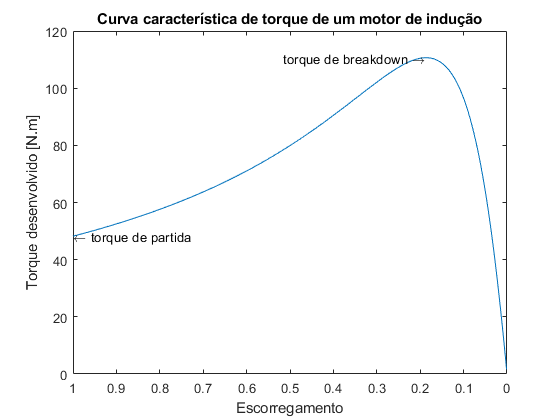

figure; % abre uma nova figura
h1 = axes; % h1 controla os eixos do gráfico

% plote um gráfico s por Td
______________
 
set(h1, 'Xdir', 'reverse'); % inverte a escala do eixo x

xlabel('Escorregamento');
ylabel('Torque desenvolvido [N.m]');
title('Curva característica de torque de um motor de indução');


% plotagem dos detalhes das setas
partida = '\leftarrow torque de partida'; 
text(s(1), Td(1), partida);
breakdown = 'torque de breakdown \rightarrow';
[maximo, index] = max(Td);
text(s(index), Td(index), breakdown, 'HorizontalAlignment', 'right');